clear; close all; clc;
rng(0);  % For reproducibility

%% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

%% Forward chaining settings
initLen   = 365;   % first fold: 1-year training
stepLen   = 90;    % then roll by 90 days
h         = 7      % h-step ahead prediction

h = 7

N         = numel(yTrainAll);

nFolds    = floor((N - initLen) / stepLen);
fprintf('Total folds: %d\n', nFolds);

Total folds: 12



%% Model / config settings
lagListLSTM = [10 90 180];
lagListAR   = [10 90 180];   % AR(p) configurations
lagListRNN  = [10 90 180];   % RNN visible history via delays 1:p
lagListTrans  = [10 90 180]; 
nCfg        = numel(lagListAR);

numHiddenRNN  = 16;
numHiddenLSTM = 16;

%% Storage for RMSE
rmseAR_uni    = nan(nFolds, nCfg);   % folds × configs
rmseRNN_uni   = nan(nFolds, nCfg);
rmseLSTM_uni  = nan(nFolds, nCfg);
rmseTRANS_uni = nan(nFolds, nCfg);

%% Forward chaining over folds
for k = 1:nFolds
    
    % Training indices: from day 1 to "1 year + (k-1)*stepLen"
    idxTrain = 1 : (initLen + (k-1)*stepLen);
    
    % Validation indices: the next 'stepLen' days
    idxVal   = (initLen + (k-1)*stepLen + 1) : ...
               (initLen + k*stepLen);
    
    yTrain_raw = yTrainAll(idxTrain);
    yVal_raw   = yTrainAll(idxVal);

    % Normalization (only using training statistics)
    mu  = mean(yTrain_raw);
    sig = std(yTrain_raw);
    if sig == 0, sig = 1; end

    yTrain = (yTrain_raw - mu) / sig;
    yVal   = (yVal_raw   - mu) / sig;

    Ntr = numel(yTrain);

    %% 1. LSTM with window pLSTM (loop over lagListLSTM)
    for c = 1:nCfg
        pLSTM = lagListLSTM(c);           % visible history length for LSTM
        numHiddenLSTM = 16;
    
        if Ntr <= pLSTM + 1
            warning('Fold %d, LSTM(p=%d): training length too short. Skipping.', k, pLSTM);
            continue;   % leave rmseLSTM_uni(k,c) = NaN
        end
    
        %  Build 1-step-ahead training set with window pLSTM
        numSeqLSTM = Ntr - pLSTM;        % require t + pLSTM <= Ntr
        XTrainLSTM = cell(numSeqLSTM,1);
        YTrainLSTM = zeros(numSeqLSTM,1);
    
        for t = 1:numSeqLSTM
            XTrainLSTM{t} = yTrain(t : t + pLSTM - 1)';   % 1 × pLSTM sequence
            YTrainLSTM(t) = yTrain(t + pLSTM);            % 1-step target
        end
    
        layers = [ ...
            sequenceInputLayer(1)
            lstmLayer(numHiddenLSTM,'OutputMode','last')
            fullyConnectedLayer(1)
            regressionLayer];
    
        options = trainingOptions('adam', ...
            'MaxEpochs', 60, ...
            'GradientThreshold', 1, ...
            'InitialLearnRate', 0.01, ...
            'Verbose', false, ...
            'Plots','none');
    
        netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);
    
        % Recursive h-step-ahead validation
        y_true_all = [yTrain; yVal];
        nVal = numel(yVal);
    
        % Store prediction for each validation day
        YValPred_LSTMn_full = zeros(nVal,1);
    
        for tVal = 1:nVal
            % Full index in the combined series
            idxEnd   = Ntr + tVal - 1;
            idxStart = idxEnd - pLSTM + 1;
            if idxStart < 1
                idxStart = 1;
            end
    
            histY = y_true_all(idxStart:idxEnd);
    
            % Left-pad if history too short
            if numel(histY) < pLSTM
                pad = pLSTM - numel(histY);
                histY = [repmat(histY(1), pad, 1); histY];
            end
    
            % Recursive h-step prediction
            for step = 1:h
                seq = {histY'};   % 1 × pLSTM
                yhat = predict(netLSTM, seq, "MiniBatchSize",1);
                if iscell(yhat), yhat = yhat{1}; end
                yhat = yhat(end); % scalar
    
                histY = [histY(2:end); yhat];  % slide window
            end
    
            YValPred_LSTMn_full(tVal) = histY(end);
        end
    
        % Align with AR-style targets
        YValTrue_LSTMn = yVal(h:end);                    % true values
        YValPred_LSTMn = YValPred_LSTMn_full(1:end-h+1); % predictions
    
        % Safety alignment
        Lp = min(length(YValTrue_LSTMn), length(YValPred_LSTMn));
        YValTrue_LSTMn = YValTrue_LSTMn(end-Lp+1:end);
        YValPred_LSTMn = YValPred_LSTMn(end-Lp+1:end);
    
        % Denormalize
        YValPred_LSTM = (YValPred_LSTMn * sig + mu).';
        YValTrue_LSTM = (YValTrue_LSTMn * sig + mu).';
    
        % Save RMSE: fold k, config c
        rmseLSTM_uni(k,c) = sqrt(mean((YValPred_LSTM - YValTrue_LSTM).^2));
    end

    %% 2. Loop over different visible history lengths p
    for c = 1:nCfg
        pAR  = lagListAR(c);    % AR(p)
        pRNN = lagListRNN(c);   % RNN delays 1:pRNN
        pTrans = lagListTrans(c);  % Transformer sequence lentgh

        %% AR(p) baseline via linear regression (fitlm) + warm start
        if Ntr <= pAR + 1
            warning('Fold %d, AR(%d): training length too short. Skipping.', k, pAR);
        else
            N_eff = Ntr - pAR - h + 1;

            Xtr_AR = zeros(N_eff, pAR);
            Ytr_AR = zeros(N_eff, 1);
            
            for t = 1:N_eff
                % Input: p AR lags
                Xtr_AR(t, :) = yTrain(t + pAR - 1 : -1 : t).';   % reverse slice for convenience
                
                % Target: value h steps ahead
                Ytr_AR(t) = yTrain(t + pAR - 1 + h);
            end

            mdlAR = fitlm(Xtr_AR, Ytr_AR);
            
            % Concatenate full ground truth data (Train + Val)
            y_true_all = [yTrain; yVal];

            % Initialize container for validation predictions
            YValPred_AR_norm = zeros(numel(yVal), 1);

            % Loop over each time step in the validation set
            for t = 1:numel(yVal)
            
                % Start with true history available at this validation time
                idxEnd   = Ntr + t - 1;
                idxStart = idxEnd - pAR + 1;
                histVals = y_true_all(idxStart:idxEnd);   % p AR lags
            
                % Recursively predict until step = 7
                for step = 1:h
                    x = histVals(end-pAR+1:end)';   % last p lags as a row
                    yhat = predict(mdlAR, x);
                    histVals = [histVals; yhat];    % append prediction
                end
            
                % Store ONLY the 7th-step prediction
                YValPred_AR_norm(t) = histVals(end);
            end

            YValTrue_norm = yVal(h:end);
            YValPred_AR_norm = YValPred_AR_norm(1:end-h+1);

            % Align lengths (Safety check, though lengths should match now)
            lenPred = length(YValPred_AR_norm);
            lenTrue = length(YValTrue_norm);
            if lenTrue > lenPred
                YValTrue_norm = YValTrue_norm(end-lenPred+1:end);
            elseif lenPred > lenTrue
                YValPred_AR_norm = YValPred_AR_norm(end-lenTrue+1:end);
            end

            % De-normalize
            YValPred_AR = YValPred_AR_norm * sig + mu;
            YValTrue    = YValTrue_norm * sig + mu;

            rmseAR_uni(k, c) = sqrt(mean((YValPred_AR - YValTrue).^2));
        end

        %% 2.2) RNN (layrecnet) with delays 1:pRNN + warm start, true h-step-ahead
        if Ntr <= pRNN + 2
            warning('Fold %d, RNN(p=%d): training length too short. Skipping.', k, pRNN);
        else
            % 1-step ahead training
            X_rnn = num2cell(yTrain(1:end-1)');
            T_rnn = num2cell(yTrain(2:end)');
            
            netRNN = layrecnet(1:pRNN, numHiddenRNN);
            netRNN.trainFcn = 'trainscg';
            netRNN.trainParam.showWindow = false;
            
            [Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
            netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);
            
            [~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);
        
            % Warm-started validation prediction
            nVal = numel(yVal);
            y_true_all = [yTrain; yVal];
        
            YValPred_rnn_norm = zeros(nVal - h + 1, 1);
            YValTrue_rnn_norm = yVal(h:end);
        
            for t = 1:(nVal - h + 1)
                idxEnd = Ntr + t - 1;
                idxStart = idxEnd - pRNN + 1;
                histVals = y_true_all(idxStart:idxEnd);   % last pRNN true values
            
                for step = 1:h
                    Xseq = num2cell(histVals(end-pRNN+1:end)');
                    yhat = netRNN(Xseq, Xf_rnn, Af_rnn);
                    histVals = [histVals; yhat{end}];
                end
                YValPred_rnn_norm(t) = histVals(end);
            end
        
            % De-normalize and compute RMSE
            YValPred_RNN = YValPred_rnn_norm * sig + mu;
            YValTrue_RNN = YValTrue_rnn_norm * sig + mu;
            rmseRNN_uni(k, c) = sqrt(mean((YValPred_RNN - YValTrue_RNN).^2));
        end

        %% Transformer        
        embeddingOutputSize = 1;      % Set to 1 so it matches input dimension (allows addition)
        maxPosition         = 180;    % Must be >= pTrans
        
        numHeads       = 8;
        numKeyChannels = 8 * embeddingOutputSize;
        
        % Architecture:
        % input sequence -> positional embedding -> (input + position)
        % -> self-attention -> pooling -> scalar output
        layers = [ ...
            sequenceInputLayer(1, Name="input")              % one feature per time step
            positionEmbeddingLayer(embeddingOutputSize, ...
                maxPosition, PositionDimension="temporal", ...
                Name="pos-emb")                              % temporal positional embedding
            additionLayer(2, Name="add")                     % add input + position
            selfAttentionLayer(numHeads, numKeyChannels, ...
                Name="attn")                                 % multi-head self-attention
            globalAveragePooling1dLayer(Name="gap")          % pool across time dimension
            fullyConnectedLayer(1, Name="fc")                % scalar output
            regressionLayer(Name="output")];
        
        % Connect: pos-emb -> add/in1  (automatic)
        %          input   -> add/in2  (manual)
        lgraph = layerGraph(layers);
        lgraph = connectLayers(lgraph, "input", "add/in2");
        
        % Training options
        options = trainingOptions('adam', ...
            'MaxEpochs', 50, ...
            'MiniBatchSize', 32, ...
            'Shuffle', 'every-epoch', ...
            'Verbose', false);
        
        % Construct 1-step-ahead training data
        % Input:  past pTrans values
        % Target: the next value (y(t+pTrans))
        numSequences = Ntr - pTrans;        % require t+pTrans <= Ntr
        XTrainCell   = cell(numSequences,1);
        YTrain       = zeros(numSequences,1);
        
        for t = 1:numSequences
            XTrainCell{t} = yTrain(t : t + pTrans - 1)';     % 1 × pTrans sequence
            YTrain(t)     = yTrain(t + pTrans);              % next value
        end
        
        % Train Transformer: sequence -> scalar
        netTrans_uni = trainNetwork(XTrainCell, YTrain, lgraph, options);
        
        % recursive h-step-ahead prediction
        y_true_all = [yTrain; yVal];        % training + validation true values
        nVal       = numel(yVal);
        
        % We first compute predictions for each validation time index,
        % then truncate to match yVal(h:end) (same alignment as AR approach)
        YTrans_test_norm_full = zeros(nVal, 1);
        
        for tVal = 1:nVal
            % Current prediction time index in the combined series
            idxEnd = Ntr + tVal - 1;
        
            % Extract last pTrans true values before this time
            idxStart = idxEnd - pTrans + 1;
            if idxStart < 1
                idxStart = 1;
            end
            histY = y_true_all(idxStart:idxEnd);
        
            % If history length < pTrans (early folds), left-pad with first value
            if numel(histY) < pTrans
                padSize = pTrans - numel(histY);
                histY   = [repmat(histY(1), padSize, 1); histY];
            end
        
            % Recursive h-step prediction:
            % at each step: window -> 1-step prediction -> slide window
            for step = 1:h
                Yhat = predict(netTrans_uni, {histY'});       % input is 1×pTrans sequence
                if iscell(Yhat)
                    yhat_next = Yhat{1};
                else
                    yhat_next = Yhat;
                end
        
                % Slide window: discard oldest, append new prediction
                histY = [histY(2:end); yhat_next];
            end
        
            % The last value after h recursions is the h-step-ahead forecast
            YTrans_test_norm_full(tVal) = histY(end);
        end
        
        % Alignment with AR-style true values 
        % True values start from validation day h
        YValTrue_trans_norm = yVal(h:end);                 % length nVal - h + 1
        % Predictions: keep first nVal - h + 1 entries
        YTrans_test_norm    = YTrans_test_norm_full(1:end-h+1);
        
        % Safety length check (should match but keep consistent with AR code)
        lenPred = length(YTrans_test_norm);
        lenTrue = length(YValTrue_trans_norm);
        if lenTrue > lenPred
            YValTrue_trans_norm = YValTrue_trans_norm(end-lenPred+1:end);
        elseif lenPred > lenTrue
            YTrans_test_norm = YTrans_test_norm(end-lenTrue+1:end);
        end
        
        % Denormalize
        YTrans_test    = YTrans_test_norm    * sig + mu;
        YValTrue_trans = YValTrue_trans_norm * sig + mu;
        
        % Store RMSE for this fold / this config
        rmseTRANS_uni(k,c) = sqrt(mean((YTrans_test - YValTrue_trans).^2));

    end

    %% Fold summary print
    fprintf("========== Fold %2d ==========", k);
    for c = 1:nCfg
        fprintf("   Config p=%3d | AR RMSE = %.4f | RNN RMSE = %.4f | LSTM RMSE = %.4f |TRANS RMSE = %.4f\n", ...
            lagListAR(c), rmseAR_uni(k,c), rmseRNN_uni(k,c), rmseLSTM_uni(k,c), rmseTRANS_uni(k,c));

    end
end

========== Fold  1 ==========

   Config p= 10 | AR RMSE = 2.3782 | RNN RMSE = 3.3082 | LSTM RMSE = 2.2793 |TRANS RMSE = 2.3851
   Config p= 90 | AR RMSE = 8.1771 | RNN RMSE = 15.8702 | LSTM RMSE = 2.8581 |TRANS RMSE = 5.0127
   Config p=180 | AR RMSE = 11.0079 | RNN RMSE = 7.3805 | LSTM RMSE = 3.0109 |TRANS RMSE = 5.7960


========== Fold  2 ==========

   Config p= 10 | AR RMSE = 3.1182 | RNN RMSE = 4.9133 | LSTM RMSE = 2.8230 |TRANS RMSE = 3.1415
   Config p= 90 | AR RMSE = 16.3894 | RNN RMSE = 3.5832 | LSTM RMSE = 2.8995 |TRANS RMSE = 6.6617
   Config p=180 | AR RMSE = 15.7064 | RNN RMSE = 14.8840 | LSTM RMSE = 3.3704 |TRANS RMSE = 10.1566


========== Fold  3 ==========

   Config p= 10 | AR RMSE = 2.5203 | RNN RMSE = 3.5108 | LSTM RMSE = 2.1692 |TRANS RMSE = 2.4562
   Config p= 90 | AR RMSE = 4.4778 | RNN RMSE = 11.1341 | LSTM RMSE = 2.1176 |TRANS RMSE = 2.5144
   Config p=180 | AR RMSE = 15.4160 | RNN RMSE = 12.1775 | LSTM RMSE = 2.2489 |TRANS RMSE = 3.5728


========== Fold  4 ==========

   Config p= 10 | AR RMSE = 4.1858 | RNN RMSE = 5.8143 | LSTM RMSE = 4.1402 |TRANS RMSE = 3.9421
   Config p= 90 | AR RMSE = 12.5115 | RNN RMSE = 18.2336 | LSTM RMSE = 3.5814 |TRANS RMSE = 4.0577
   Config p=180 | AR RMSE = 13.5224 | RNN RMSE = 8.5079 | LSTM RMSE = 3.5275 |TRANS RMSE = 5.5608


========== Fold  5 ==========

   Config p= 10 | AR RMSE = 3.2132 | RNN RMSE = 3.1135 | LSTM RMSE = 3.2340 |TRANS RMSE = 3.0841
   Config p= 90 | AR RMSE = 11.2648 | RNN RMSE = 6.8314 | LSTM RMSE = 3.4547 |TRANS RMSE = 4.4303
   Config p=180 | AR RMSE = 14.4917 | RNN RMSE = 10.2137 | LSTM RMSE = 3.3041 |TRANS RMSE = 4.0317


========== Fold  6 ==========

   Config p= 10 | AR RMSE = 3.5266 | RNN RMSE = 3.2091 | LSTM RMSE = 3.1357 |TRANS RMSE = 3.3723
   Config p= 90 | AR RMSE = 14.1848 | RNN RMSE = 8.2981 | LSTM RMSE = 3.3418 |TRANS RMSE = 3.3857
   Config p=180 | AR RMSE = 12.4577 | RNN RMSE = 5.7361 | LSTM RMSE = 3.5737 |TRANS RMSE = 2.9375


========== Fold  7 ==========

   Config p= 10 | AR RMSE = 2.1154 | RNN RMSE = 1.8756 | LSTM RMSE = 1.9622 |TRANS RMSE = 2.0386
   Config p= 90 | AR RMSE = 3.2539 | RNN RMSE = 6.3108 | LSTM RMSE = 1.9758 |TRANS RMSE = 2.8551
   Config p=180 | AR RMSE = 12.5437 | RNN RMSE = 11.3337 | LSTM RMSE = 1.9912 |TRANS RMSE = 2.5389


========== Fold  8 ==========

   Config p= 10 | AR RMSE = 3.0905 | RNN RMSE = 6.1041 | LSTM RMSE = 3.0649 |TRANS RMSE = 2.4835
   Config p= 90 | AR RMSE = 10.1250 | RNN RMSE = 10.4001 | LSTM RMSE = 2.8266 |TRANS RMSE = 3.1015
   Config p=180 | AR RMSE = 10.8894 | RNN RMSE = 5.2246 | LSTM RMSE = 2.5374 |TRANS RMSE = 6.3889


========== Fold  9 ==========

   Config p= 10 | AR RMSE = 2.8175 | RNN RMSE = 3.7631 | LSTM RMSE = 2.8566 |TRANS RMSE = 2.8874
   Config p= 90 | AR RMSE = 9.4462 | RNN RMSE = 10.5968 | LSTM RMSE = 2.7084 |TRANS RMSE = 6.9577
   Config p=180 | AR RMSE = 11.4416 | RNN RMSE = 14.1287 | LSTM RMSE = 2.6617 |TRANS RMSE = 3.6422


========== Fold 10 ==========

   Config p= 10 | AR RMSE = 3.2265 | RNN RMSE = 4.8497 | LSTM RMSE = 3.0386 |TRANS RMSE = 3.2628
   Config p= 90 | AR RMSE = 14.4099 | RNN RMSE = 6.2912 | LSTM RMSE = 2.7132 |TRANS RMSE = 2.6388
   Config p=180 | AR RMSE = 12.1503 | RNN RMSE = 2.9261 | LSTM RMSE = 3.3167 |TRANS RMSE = 3.2044


========== Fold 11 ==========

   Config p= 10 | AR RMSE = 2.3242 | RNN RMSE = 2.0877 | LSTM RMSE = 2.2718 |TRANS RMSE = 2.3473
   Config p= 90 | AR RMSE = 3.5251 | RNN RMSE = 1.9534 | LSTM RMSE = 2.4118 |TRANS RMSE = 2.4135
   Config p=180 | AR RMSE = 12.8837 | RNN RMSE = 15.1360 | LSTM RMSE = 2.4280 |TRANS RMSE = 2.5302


========== Fold 12 ==========

   Config p= 10 | AR RMSE = 2.3792 | RNN RMSE = 3.5531 | LSTM RMSE = 2.2243 |TRANS RMSE = 1.7338
   Config p= 90 | AR RMSE = 7.3001 | RNN RMSE = 6.5273 | LSTM RMSE = 1.9684 |TRANS RMSE = 1.8226
   Config p=180 | AR RMSE = 8.5913 | RNN RMSE = 6.2327 | LSTM RMSE = 2.4397 |TRANS RMSE = 2.1618


%% Overall RMSE summary (mean over folds)
meanAR    = mean(rmseAR_uni,    1, 'omitnan');   % 1 × nCfg
meanRNN   = mean(rmseRNN_uni,   1, 'omitnan');
meanLSTM  = mean(rmseLSTM_uni,  1, 'omitnan');
meanTRANS = mean(rmseTRANS_uni, 1, 'omitnan');

fprintf("\n=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===\n");


=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===


for c = 1:nCfg
    fprintf("AR(%3d)            : %.4f\n", lagListAR(c),    meanAR(c));
end

AR( 10)            : 2.9080
AR( 90)            : 9.5888
AR(180)            : 12.5918


for c = 1:nCfg
    fprintf("RNN(1:%3d)        : %.4f\n", lagListRNN(c),   meanRNN(c));
end

RNN(1: 10)        : 3.8419
RNN(1: 90)        : 8.8359
RNN(1:180)        : 9.4901


for c = 1:nCfg
    fprintf("LSTM(p=%3d)       : %.4f\n", lagListLSTM(c),  meanLSTM(c));
end

LSTM(p= 10)       : 2.7666
LSTM(p= 90)       : 2.7381
LSTM(p=180)       : 2.8675


for c = 1:nCfg
    fprintf("Transformer(p=%3d): %.4f\n", lagListTrans(c), meanTRANS(c));
end

Transformer(p= 10): 2.7612
Transformer(p= 90): 3.8210
Transformer(p=180): 4.3768


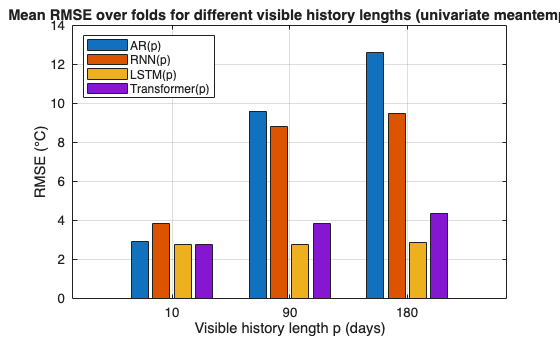


%% mean RMSE vs visible history length (bar chart)
figure;

xCats = categorical(string(lagListAR));
xCats = reordercats(xCats, string(lagListAR));

% Each column: one model family; each row: one p
barData = [meanAR(:) meanRNN(:) meanLSTM(:) meanTRANS(:)];
bar(xCats, barData);
ylabel('RMSE (°C)');
xlabel('Visible history length p (days)');
title('Mean RMSE over folds for different visible history lengths (univariate meantemp)');
legend({'AR(p)','RNN(p)','LSTM(p)','Transformer(p)'}, 'Location','northwest');
grid on;

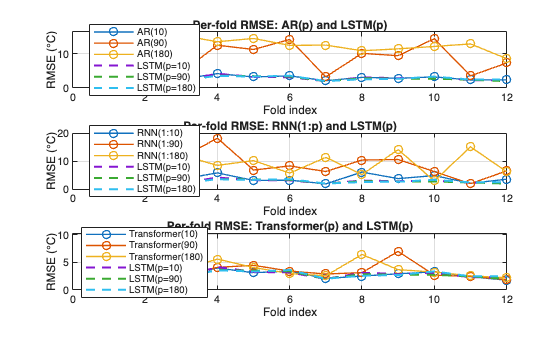


%% per-fold RMSE curves
figure;
tFolds = 1:nFolds;

% AR curves vs LSTM(p)
subplot(3,1,1);
plot(tFolds, rmseAR_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, '--', 'LineWidth', 1.5);  % one line per p
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: AR(p) and LSTM(p)');
legendStringsAR   = arrayfun(@(p)sprintf('AR(%d)',p),       lagListAR,   'UniformOutput', false);
legendStringsLSTM = arrayfun(@(p)sprintf('LSTM(p=%d)',p),   lagListLSTM, 'UniformOutput', false);
legend([legendStringsAR legendStringsLSTM], 'Location','best');

% RNN curves vs LSTM(p)
subplot(3,1,2);
plot(tFolds, rmseRNN_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, '--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: RNN(1:p) and LSTM(p)');
legendStringsRNN = arrayfun(@(p)sprintf('RNN(1:%d)',p), lagListRNN, 'UniformOutput', false);
legend([legendStringsRNN legendStringsLSTM], 'Location','best');

% Transformer curves vs LSTM(p)
subplot(3,1,3);
plot(tFolds, rmseTRANS_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, '--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: Transformer(p) and LSTM(p)');
legendStringsTrans = arrayfun(@(p)sprintf('Transformer(%d)',p), lagListTrans, 'UniformOutput', false);
legend([legendStringsTrans legendStringsLSTM], 'Location','best');

%% Final comparison on TEST set (AR vs RNN vs LSTM with warm start for AR & RNN)
clear; close all; clc;
rng(0);  % For reproducibility

% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

% 1. Normalization based on TRAIN only 
mu  = mean(yTrainAll);
sig = std(yTrainAll);
if sig == 0, sig = 1; end

yTrain = (yTrainAll - mu) / sig;
yTest  = (yTestAll  - mu) / sig;

y_true_all = [yTrain; yTest];  % train + test combined (for convenience)

%% 2. AR baseline on test set (recursive h-step ahead)

noLagsAR = 10;
h        = 7;
Ntr      = numel(yTrain);
nTest    = numel(yTest);

if Ntr <= noLagsAR + 1
    error("Training series too short for AR(%d).", noLagsAR);
end

% ---- 2.1 Train 1-step-ahead AR(noLagsAR) on train data ----
N_eff = Ntr - noLagsAR;
Xtr_AR = zeros(N_eff, noLagsAR);
Ytr_AR = zeros(N_eff, 1);

for t = 1:N_eff
    % Last noLagsAR lags at time t+noLagsAR-1
    Xtr_AR(t, :) = yTrain(t + noLagsAR - 1 : -1 : t).';
    % 1-step ahead target
    Ytr_AR(t)    = yTrain(t + noLagsAR);
end

mdlAR = fitlm(Xtr_AR, Ytr_AR);

% ---- 2.2 Recursive h-step-ahead predictions on test ----
Y_AR_test_norm_full = zeros(nTest, 1);

for t = 1:nTest
    % Last available index (global) at this test time
    idxEnd = Ntr + t - 1;
    idxStart = idxEnd - noLagsAR + 1;
    if idxStart < 1
        idxStart = 1;
    end

    % Initial history from true values
    histVals = y_true_all(idxStart : idxEnd);

    % If history is shorter than noLagsAR (very early), left-pad
    if numel(histVals) < noLagsAR
        padSize = noLagsAR - numel(histVals);
        histVals = [repmat(histVals(1), padSize, 1); histVals];
    end

    % Recursively predict h steps ahead
    for step = 1:h
        x = histVals(end-noLagsAR+1:end).';     % last noLagsAR lags
        yhat = predict(mdlAR, x);               % 1-step ahead
        histVals = [histVals; yhat];            % append prediction
    end

    % h-step ahead prediction at this test time
    Y_AR_test_norm_full(t) = histVals(end);
end

% Keep only the first nTest-h+1 predictions to align with yTest(h:end)
Y_AR_test_norm = Y_AR_test_norm_full(1:end-h+1);

%% 3. RNN (layrecnet, delays 1:pRNN) on test set (recursive h-step ahead)

% ---- 3.1 1-step-ahead training on train data ----
X_rnn = num2cell(yTrain(1:end-1)');   % 1-step inputs
T_rnn = num2cell(yTrain(2:end)');     % 1-step targets

pRNN         = 10;
numHiddenRNN = 16;
netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

[~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);

% ---- 3.2 Recursive h-step-ahead RNN test predictions ----
Y_RNN_test_norm_full = zeros(nTest, 1);

for t = 1:nTest
    % Last pRNN true values available at this test time
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pRNN + 1;
    if idxStart < 1
        idxStart = 1;
    end
    histVals = y_true_all(idxStart:idxEnd);

    % If history shorter than pRNN, left-pad
    if numel(histVals) < pRNN
        padSize  = pRNN - numel(histVals);
        histVals = [repmat(histVals(1), padSize, 1); histVals];
    end

    % Recursively predict h steps ahead
    for step = 1:h
        Xseq = num2cell(histVals(end-pRNN+1:end)');  % last pRNN values
        yhat = netRNN(Xseq, Xf_rnn, Af_rnn);         % 1-step ahead
        histVals = [histVals; yhat{end}];            % append prediction
    end

    % h-step-ahead prediction
    Y_RNN_test_norm_full(t) = histVals(end);
end

Y_RNN_test_norm = Y_RNN_test_norm_full(1:end-h+1);

%% 4. LSTM on test set (1-step training + recursive h-step prediction)

pLSTM = 10;
numHiddenLSTM = 16;
% Build 1-step-ahead training samples 
numSeqLSTM = Ntr - pLSTM;         % require t+pLSTM <= Ntr
XTrainLSTM = cell(numSeqLSTM,1);
YTrainLSTM = zeros(numSeqLSTM,1);

for t = 1:numSeqLSTM
    XTrainLSTM{t} = yTrain(t : t+pLSTM-1)';   % window (1 × pLSTM)
    YTrainLSTM(t) = yTrain(t + pLSTM);        % next value
end

% Build LSTM model
layers = [ ...
    sequenceInputLayer(1)
    lstmLayer(numHiddenLSTM, 'OutputMode','last')
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

% Recursive h-step ahead prediction on test
nTest = numel(yTest);
y_true_all = [yTrain; yTest];

Y_LSTM_test_norm_full = zeros(nTest,1);

for t = 1:nTest
    % full index in combined train+test series
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pLSTM + 1;
    if idxStart < 1
        idxStart = 1;
    end
    
    % last pLSTM true values
    histY = y_true_all(idxStart:idxEnd);

    % left-pad if too short
    if numel(histY) < pLSTM
        pad = pLSTM - numel(histY);
        histY = [repmat(histY(1), pad, 1); histY];
    end

    % recursive h-step ahead
    for step = 1:h
        seq = {histY'};                       % 1×pLSTM
        yhat = predict(netLSTM, seq, 'MiniBatchSize',1);
        if iscell(yhat), yhat = yhat{1}; end
        yhat = yhat(end);                     % scalar
        histY = [histY(2:end); yhat];         % slide window
    end

    % final h-step prediction
    Y_LSTM_test_norm_full(t) = histY(end);
end

% keep predictions aligned with yTest(h:end)
Y_LSTM_test_norm = Y_LSTM_test_norm_full(1:end-h+1);
YTrue_LSTM_test_norm = yTest(h:end);

%% 5. Transformer on test set (1-step training + recursive h-step prediction)

pTrans             = 10;
embeddingOutputSize = 1;
maxPosition         = 180;
numHeads            = 8;
numKeyChannels      = 8 * embeddingOutputSize;

% ---- 5.1 Define Transformer-like network: sequence -> scalar (1-step) ----
layers = [ ...
    sequenceInputLayer(1, Name="input")
    positionEmbeddingLayer(embeddingOutputSize, maxPosition, ...
        PositionDimension="temporal", Name="pos-emb")
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads, numKeyChannels, Name="attn")
    globalAveragePooling1dLayer(Name="gap")
    fullyConnectedLayer(1, Name="fc")
    regressionLayer(Name="output")];

lgraph = layerGraph(layers);
% Connect raw input to the second input of the addition layer
lgraph = connectLayers(lgraph, "input", "add/in2");

options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

% 5.2 1-step-ahead training windows from yTrain
numSequences = Ntr - pTrans;      % t+pTrans <= Ntr
XTrainCell   = cell(numSequences,1);
YTrainTrans  = zeros(numSequences,1);

for t = 1:numSequences
    % Input window: pTrans past values
    XTrainCell{t} = yTrain(t : t+pTrans-1)';   % 1 × pTrans
    % 1-step-ahead target: next value after the window
    YTrainTrans(t) = yTrain(t + pTrans);
end

netTrans_uni = trainNetwork(XTrainCell, YTrainTrans, lgraph, options);

% ---- 5.3 Recursive h-step-ahead Transformer predictions on test ----
YTrans_test_norm_full = zeros(nTest, 1);

for t = 1:nTest
    % Last index at this test time
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pTrans + 1;
    if idxStart < 1
        idxStart = 1;
    end

    histY = y_true_all(idxStart:idxEnd);

    % If history shorter than pTrans, left-pad with earliest value
    if numel(histY) < pTrans
        padSize = pTrans - numel(histY);
        histY   = [repmat(histY(1), padSize, 1); histY];
    end

    % Recursively predict h steps ahead
    for step = 1:h
        Yhat = predict(netTrans_uni, {histY'});   % input: 1 × pTrans
        if iscell(Yhat)
            yhat_next = Yhat{1};
        else
            yhat_next = Yhat;
        end
        % Slide window: drop oldest, append prediction
        histY = [histY(2:end); yhat_next];
    end

    % h-step-ahead prediction
    YTrans_test_norm_full(t) = histY(end);
end

YTrans_test_norm = YTrans_test_norm_full(1:end-h+1);

%% 6. RMSE (align all models to the same horizon)

% Ground truth for h-step-ahead: from day h to end of test
Y_true_test_norm = yTest(h:end);

lenAR    = length(Y_AR_test_norm);
lenRNN   = length(Y_RNN_test_norm);
lenLSTM  = length(Y_LSTM_test_norm);
lenTrans = length(YTrans_test_norm);
lenTrue  = length(Y_true_test_norm);

L = min([lenAR, lenRNN, lenLSTM, lenTrans, lenTrue]);

Y_AR_test_norm    = Y_AR_test_norm(end-L+1:end);
Y_RNN_test_norm   = Y_RNN_test_norm(end-L+1:end);
Y_LSTM_test_norm  = Y_LSTM_test_norm(end-L+1:end);
YTrans_test_norm  = YTrans_test_norm(end-L+1:end);
Y_true_test_norm  = Y_true_test_norm(end-L+1:end);

% Denormalize
Y_AR_test    = Y_AR_test_norm   * sig + mu;
Y_RNN_test   = Y_RNN_test_norm  * sig + mu;
Y_LSTM_test  = Y_LSTM_test_norm * sig + mu;
Y_TRANS_test = YTrans_test_norm * sig + mu;
Y_true_test  = Y_true_test_norm * sig + mu;
Y_LSTM_test  = Y_LSTM_test(:);  % ensure column vector

% RMSE
rmseAR    = sqrt(mean((Y_AR_test    - Y_true_test).^2));
rmseRNN   = sqrt(mean((Y_RNN_test   - Y_true_test).^2));
rmseLSTM  = sqrt(mean((Y_LSTM_test  - Y_true_test).^2));
rmseTRANS = sqrt(mean((Y_TRANS_test - Y_true_test).^2));

fprintf('Test RMSE | AR(p=%d)=%.4f | RNN(p=%d)=%.4f | LSTM(p=%d)=%.4f | TRANS(p=%d)=%.4f\n', ...
        noLagsAR, rmseAR, pRNN, rmseRNN, pLSTM, rmseLSTM, pTrans, rmseTRANS);

Test RMSE | AR(p=10)=3.9147 | RNN(p=10)=7.0787 | LSTM(p=10)=3.4921 | TRANS(p=10)=3.7676


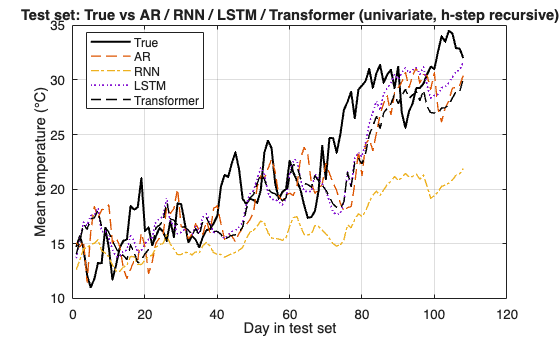


%% 7. Plot

figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--',  'LineWidth', 1);
plot(Y_RNN_test,  '-.',  'LineWidth', 1);
plot(Y_LSTM_test, ':',   'LineWidth', 1.2);
plot(Y_TRANS_test,'--k', 'LineWidth', 1.1);

legend('True','AR','RNN','LSTM','Transformer','Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title('Test set: True vs AR / RNN / LSTM / Transformer (univariate, h-step recursive)');
grid on;

%% Multivariate
clear; close all; clc;
rng(0);  % For reproducibility

% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

% State variables (4-D): [temp, humidity, wind_speed, meanpressure]
varsTrain = [trainData.meantemp, trainData.humidity, ...
             trainData.wind_speed, trainData.meanpressure];
varsTest  = [testData.meantemp,  testData.humidity, ...
             testData.wind_speed, testData.meanpressure];

[numTrain, numVars] = size(varsTrain);   % numVars = 4
yTestAll = testData.meantemp;

%% Normalization (per variable, using TRAIN only)
muX  = mean(varsTrain, 1);
sigX = std(varsTrain, 0, 1);
sigX(sigX == 0) = 1;

XTrain = (varsTrain - muX) ./ sigX;      % numTrain × 4
XTest  = (varsTest  - muX) ./ sigX;

% For temperature de-normalization, use the first variable's stats
muTemp  = muX(1);
sigTemp = sigX(1);

%% Common settings for multivariate models
p   = 10;   % window length (visible history, in days)
h   = 7;    % forecast horizon (days ahead)
Ntr = numTrain;
nTest = size(XTest,1);
numStates = numVars;  % 4 state components

%% Multivariate AR (linear VAR) with window p, recursive h-step

if Ntr <= p + 1
    error("Training series too short for AR(p=%d).", p);
end

% Build 1-step-ahead training set: window of states -> next state
numSamplesAR = Ntr - p;                    % t+p <= Ntr
Xtr_AR = zeros(numSamplesAR, p * numStates);
Ytr_AR = zeros(numSamplesAR, numStates);   % full 4-D state as target

for t = 1:numSamplesAR
    % State window: S(t : t+p-1, :) = XTrain(t : t+p-1, :)
    winS = XTrain(t : t+p-1, :);           % p × 4
    winS = flipud(winS);                   % latest first
    Xtr_AR(t, :) = winS(:)';               % 1 × (p*4)

    % Target: next state S(t+p,:)
    Ytr_AR(t, :) = XTrain(t + p, :);       % 1 × 4
end

% Fit one linear model per state dimension (VAR approximation)
mdlAR = cell(numStates,1);
for j = 1:numStates
    mdlAR{j} = fitlm(Xtr_AR, Ytr_AR(:,j));
end

% Recursive h-step-ahead prediction on test set
S_true_all = [XTrain; XTest];             % full normalized state: train + test

S_AR_pred_norm = zeros(nTest - h + 1, numStates);  % store h-step-ahead state

for t0 = 1:(nTest - h + 1)
    % Forecast origin: last time where state is still "known"
    idxOrigin = Ntr + t0 - 1;             % global index in S_true_all

    % Initial history: last p true states up to origin
    idxStart = idxOrigin - p + 1;
    if idxStart < 1
        idxStart = 1;
    end
    histS = S_true_all(idxStart:idxOrigin, :);  % (#hist × 4)

    % If history shorter than p (shouldn't happen for reasonable Ntr), left-pad
    if size(histS,1) < p
        pad = p - size(histS,1);
        histS = [repmat(histS(1,:), pad, 1); histS];
    end

    % Recursive h-step forecasting of the full state
    for step = 1:h
        winS = histS(end-p+1:end, :);   % p × 4
        winS = flipud(winS);            % latest first
        xRow = winS(:)';                % 1 × (p*4)

        % Predict next state S_next (4-D)
        S_next = zeros(1, numStates);
        for j = 1:numStates
            S_next(j) = predict(mdlAR{j}, xRow);
        end

        % Append prediction
        histS = [histS; S_next];
    end

    % After h recursive steps, histS(end,:) is the h-step-ahead predicted state
    S_AR_pred_norm(t0, :) = histS(end, :);
end

% Temperature predictions = first state component, de-normalized
Y_AR_test = S_AR_pred_norm(:,1) * sigTemp + muTemp;
Y_true_test = yTestAll(h:end);


%% Multivariate RNN (layrecnet) predicting full state, recursive h-step

% 1-step-ahead training: input S(t), target S(t+1)
STrain = XTrain;   % alias
X_rnn = cell(1, Ntr-1);
T_rnn = cell(1, Ntr-1);

for t = 1:Ntr-1
    X_rnn{t} = STrain(t,:)';       % 4×1
    T_rnn{t} = STrain(t+1,:)';     % 4×1
end

pRNN         = p;                  % delays 1:p
numHiddenRNN = 16;

netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

% Recursive h-step-ahead prediction on test
S_true_all = [STrain; XTest];
S_RNN_pred_norm = zeros(nTest - h + 1, numStates);

for t0 = 1:(nTest - h + 1)
    idxOrigin = Ntr + t0 - 1;

    % Initial history: last p true states up to origin
    idxStart = idxOrigin - p + 1;
    if idxStart < 1
        idxStart = 1;
    end
    histS = S_true_all(idxStart:idxOrigin, :);   % (#hist × 4)
    if size(histS,1) < p
        pad = p - size(histS,1);
        histS = [repmat(histS(1,:), pad, 1); histS];
    end

    % Recursive h-step, using RNN as 1-step state predictor
    for step = 1:h
        % Build a short sequence from last p states
        Xseq = cell(1,p);
        for i = 1:p
            Xseq{i} = histS(end-p+i, :)';   % each is 4×1
        end

        % For simplicity, we reset the RNN state for each window
        Yseq_hat = netRNN(Xseq);
        S_next   = Yseq_hat{end}';         % 1×4

        histS = [histS; S_next];
    end

    S_RNN_pred_norm(t0, :) = histS(end, :);
end

Y_RNN_test = S_RNN_pred_norm(:,1) * sigTemp + muTemp;


%% Multivariate LSTM with window p, recursive h-step

pLSTM         = p;
numHiddenLSTM = 16;
inputSize     = numStates;
outputSize    = numStates;   % predict full 4-D state

if Ntr <= pLSTM + 1
    error("Training series too short for LSTM(p=%d).", pLSTM);
end

% 1-step-ahead training: window S(t:t+p-1) -> S(t+p)
numSeqLSTM = Ntr - pLSTM;
XTrainLSTM = cell(numSeqLSTM,1);
YTrainLSTM = zeros(numSeqLSTM, numStates);

for t = 1:numSeqLSTM
    % window of states: 4 × pLSTM
    XTrainLSTM{t} = XTrain(t : t+pLSTM-1, :)';
    % next state
    YTrainLSTM(t,:) = XTrain(t + pLSTM, :);
end

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenLSTM,'OutputMode','last')
    fullyConnectedLayer(outputSize)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

% Recursive h-step-ahead prediction on test
S_true_all = [XTrain; XTest];
S_LSTM_pred_norm = zeros(nTest - h + 1, numStates);

for t0 = 1:(nTest - h + 1)
    idxOrigin = Ntr + t0 - 1;
    idxStart  = idxOrigin - pLSTM + 1;
    if idxStart < 1
        idxStart = 1;
    end

    histS = S_true_all(idxStart:idxOrigin, :);
    if size(histS,1) < pLSTM
        pad = pLSTM - size(histS,1);
        histS = [repmat(histS(1,:), pad, 1); histS];
    end

    % Recursive h-step ahead:
    for step = 1:h
        winS = histS(end-pLSTM+1:end, :)';  % 4 × pLSTM
        seq  = {winS};
        Yhat = predict(netLSTM, seq, 'MiniBatchSize',1);  % output 1×4 or 4×1
        if iscell(Yhat)
            S_next = Yhat{1};
        else
            S_next = Yhat;
        end
        S_next = S_next(:)';  % 1×4
        histS  = [histS; S_next];
    end

    S_LSTM_pred_norm(t0,:) = histS(end,:);
end

Y_LSTM_test = S_LSTM_pred_norm(:,1) * sigTemp + muTemp;


%% Multivariate Transformer with window p, recursive h-step

pTrans              = p;
embeddingOutputSize = 1;
maxPosition         = 180;               % ≥ pTrans
numHeads            = 8;
numKeyChannels      = 8 * embeddingOutputSize;

layers = [ ...
    sequenceInputLayer(numStates, Name="input")                  % 4 features
    positionEmbeddingLayer(embeddingOutputSize,maxPosition, ...
        PositionDimension="temporal", Name="pos-emb")
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads, numKeyChannels, Name="attn")
    globalAveragePooling1dLayer(Name="gap")
    fullyConnectedLayer(numStates, Name="fc")                    % 4-D output
    regressionLayer(Name="output")];

lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph, "input", "add/in2");

options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

% 1-step-ahead training: window S(t:t+pTrans-1) -> S(t+pTrans)
numSeqTrans = Ntr - pTrans;
XTrainCell  = cell(numSeqTrans,1);
YTrainTrans = zeros(numSeqTrans, numStates);

for t = 1:numSeqTrans
    XTrainCell{t}  = XTrain(t : t+pTrans-1, :)';   % 4 × pTrans
    YTrainTrans(t,:) = XTrain(t + pTrans, :);      % 1 × 4
end

netTrans_multi = trainNetwork(XTrainCell, YTrainTrans, lgraph, options);

% Recursive h-step-ahead prediction on test
S_true_all = [XTrain; XTest];
S_Trans_pred_norm = zeros(nTest - h + 1, numStates);

for t0 = 1:(nTest - h + 1)
    idxOrigin = Ntr + t0 - 1;
    idxStart  = idxOrigin - pTrans + 1;
    if idxStart < 1
        idxStart = 1;
    end

    histS = S_true_all(idxStart:idxOrigin, :);
    if size(histS,1) < pTrans
        pad = pTrans - size(histS,1);
        histS = [repmat(histS(1,:), pad, 1); histS];
    end

    % Recursive h-step:
    for step = 1:h
        winS = histS(end-pTrans+1:end, :)';   % 4 × pTrans
        Yhat = predict(netTrans_multi, {winS});
        if iscell(Yhat)
            S_next = Yhat{1};
        else
            S_next = Yhat;
        end
        S_next = S_next(:)';                 % 1 × 4
        histS  = [histS; S_next];
    end

    S_Trans_pred_norm(t0,:) = histS(end,:);
end

Y_Trans_test = S_Trans_pred_norm(:,1) * sigTemp + muTemp;


%% Align lengths & compute RMSE

L = min([length(Y_AR_test), length(Y_RNN_test), ...
         length(Y_LSTM_test), length(Y_Trans_test), ...
         length(Y_true_test)]);

Y_AR_test    = Y_AR_test(end-L+1:end);
Y_RNN_test   = Y_RNN_test(end-L+1:end);
Y_LSTM_test  = Y_LSTM_test(end-L+1:end);
Y_Trans_test = Y_Trans_test(end-L+1:end);
Y_true_test  = Y_true_test(end-L+1:end);

rmseAR    = sqrt(mean((Y_AR_test    - Y_true_test).^2));
rmseRNN   = sqrt(mean((Y_RNN_test   - Y_true_test).^2));
rmseLSTM  = sqrt(mean((Y_LSTM_test  - Y_true_test).^2));
rmseTRANS = sqrt(mean((Y_Trans_test - Y_true_test).^2));

fprintf('Multivariate test RMSE (p=%d, h=%d) | AR=%.4f | RNN=%.4f | LSTM=%.4f | TRANS=%.4f\n', ...
        p, h, rmseAR, rmseRNN, rmseLSTM, rmseTRANS);

Multivariate test RMSE (p=10, h=7) | AR=3.3047 | RNN=11.6351 | LSTM=4.0400 | TRANS=3.3470


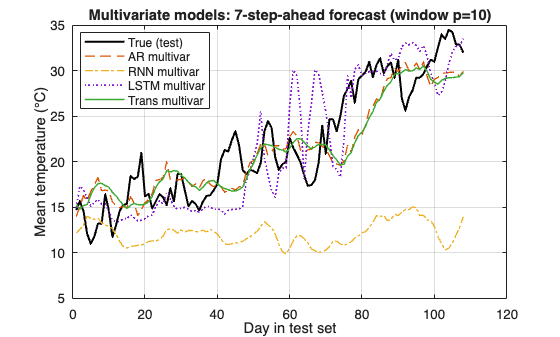


%% Plot: test truth vs four multivariate models
figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--',  'LineWidth', 1);
plot(Y_RNN_test,  '-.',  'LineWidth', 1);
plot(Y_LSTM_test, ':',   'LineWidth', 1.2);
plot(Y_Trans_test,'-',   'LineWidth', 1.1);
legend('True (test)','AR multivar','RNN multivar','LSTM multivar','Trans multivar', ...
       'Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title(sprintf('Multivariate models: %d-step-ahead forecast (window p=%d)', h, p));
grid on;